Matlab code for the Course: **Modelling and Simulation Mechatronics System**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

### Initialize by cleaning memory and widows

clear all;
close all;

### **Load the Pendulum model ODE**

% load the Pendulum model in the variable ode
mass    = 1;
ell     = 2;
gravity = 9.81;
ode     = Pendulum4EQ( mass, ell, gravity );

### Initialize 3 solver for comparison

solver_EE = ExplicitEuler();
solver_IE = ImplicitEuler();
solver_H  = Heun();

solver_EE.setODE(ode);
solver_IE.setODE(ode);
solver_H.setODE(ode);

### Set time step and inital conditions for solvers

Tmax = 5;
h    = 0.01;
tt   = 0:h:Tmax;
% setup initial condition
theta0 = pi/2;
omega0 = 0;
vel    = 0;
x0     = ell*sin(theta0);
y0     = -ell*cos(theta0);
u0     = vel*cos(theta0);
v0     = vel*sin(theta0);
ini    = [x0;y0;u0;v0];

### Compute solutions

sol_EE = solver_EE.advance( tt, ini );
sol_IE = solver_IE.advance( tt, ini );
sol_H  = solver_H.advance( tt, ini );

### Extract computed solution

x_EE = sol_EE(1,:);
y_EE = sol_EE(2,:);

x_IE = sol_IE(1,:);
y_IE = sol_IE(2,:);

x_H = sol_H(1,:);
y_H = sol_H(2,:);

### Plot computed solution

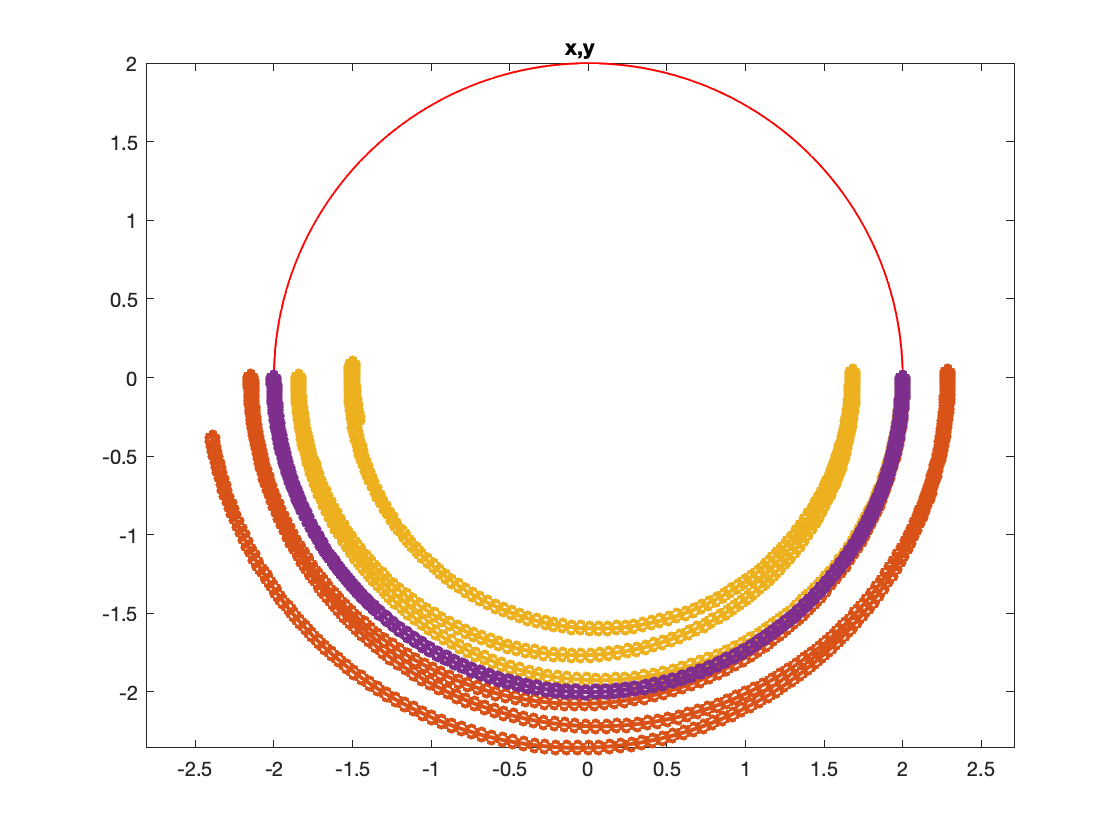

h = figure();
xx = ell*cos(0:pi/100:2*pi);
yy = ell*sin(0:pi/100:2*pi);
plot( xx, yy, '-r', 'Linewidth', 1 );
hold on
axis equal
plot( x_EE, y_EE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_IE, y_IE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_H,  y_H,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

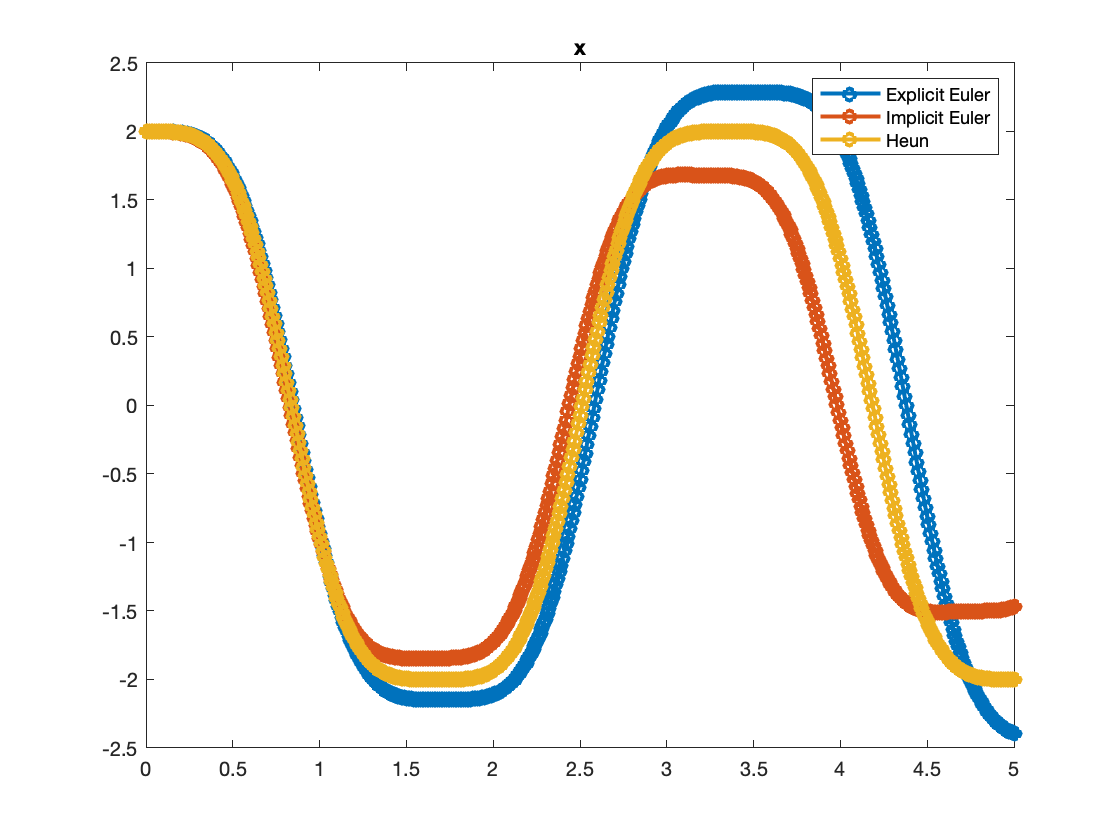

h = figure();
plot( tt, x_EE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_IE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_H,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend({'Explicit Euler', 'Implicit Euler','Heun'});
title('x');

### Make animation of the solution

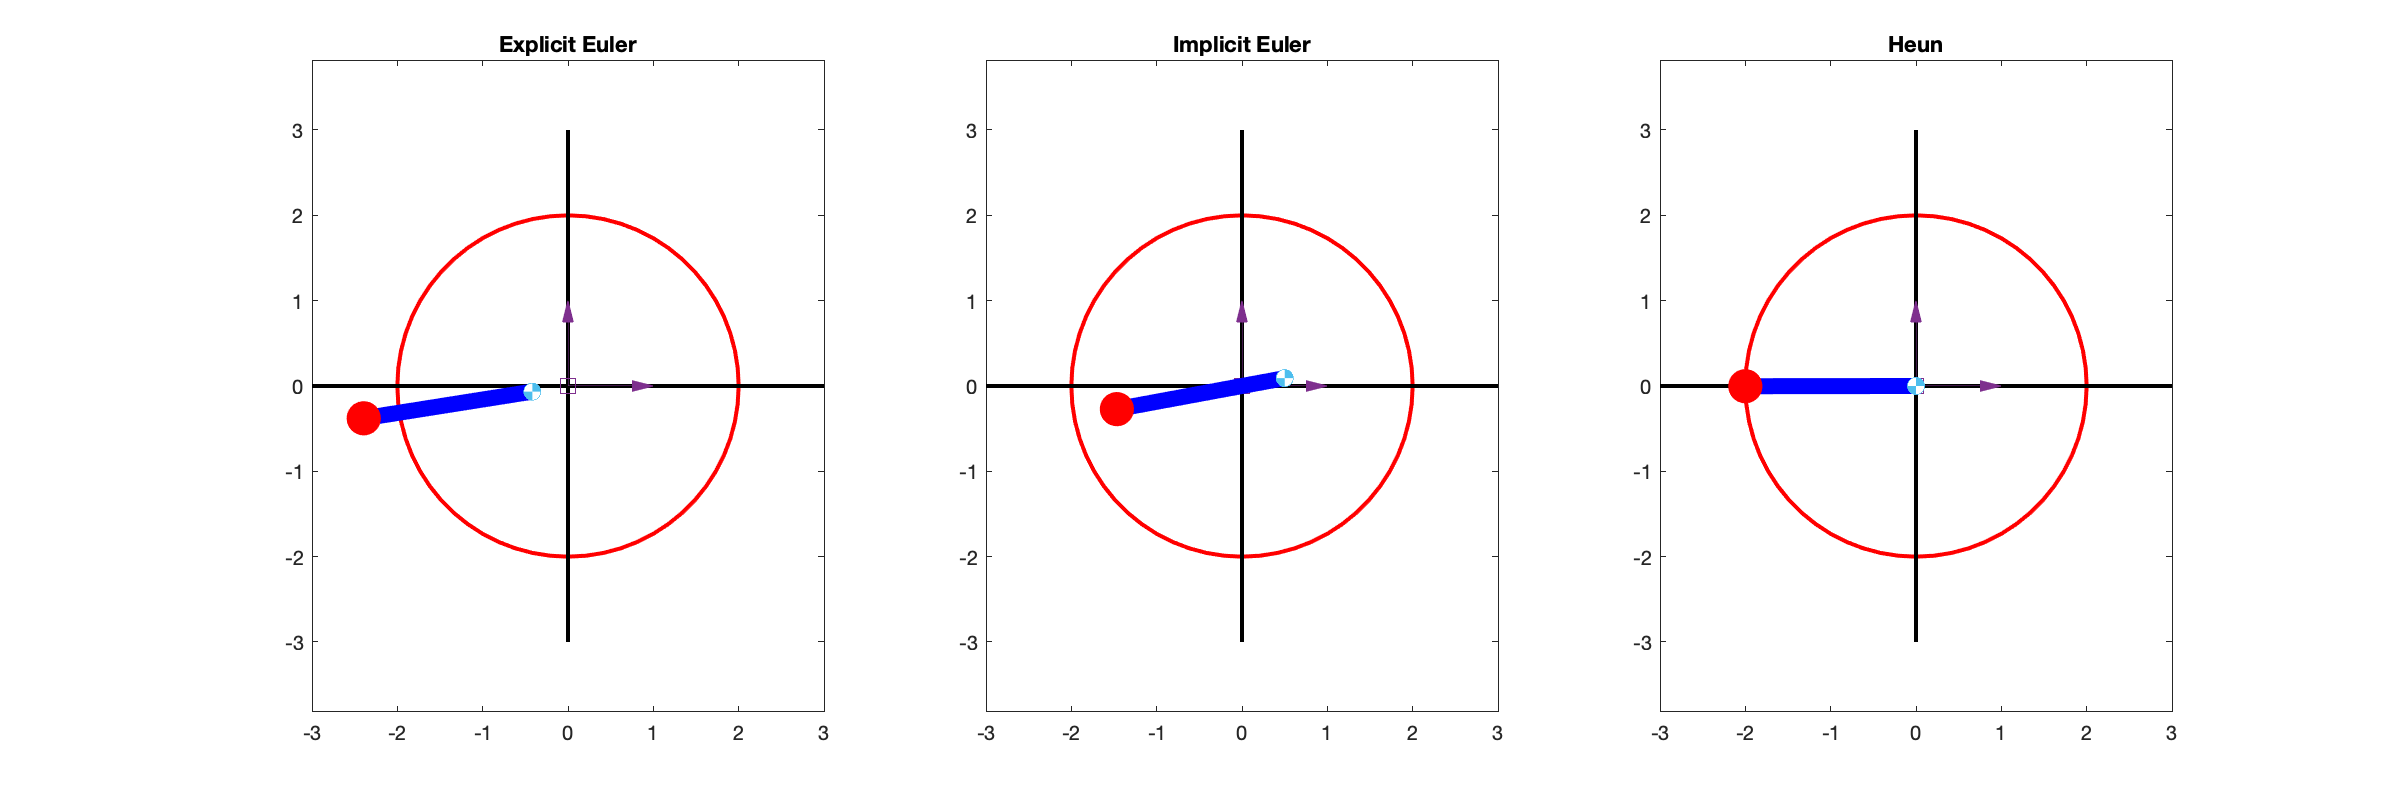

figure('Position', [1 1 1200 400]);
for k=1:10:length(tt)
  subplot(1,3,1);
  ode.plot( tt(k), sol_EE(:,k));
  title('Explicit Euler');
  subplot(1,3,2);
  ode.plot( tt(k), sol_IE(:,k));
  title('Implicit Euler');
  subplot(1,3,3);
  ode.plot( tt(k), sol_H(:,k));
  title('Heun');
  drawnow limitrate;
  pause(0.01);
end

### Compute solutions activating projection

sol_EE = solver_EE.advance( tt, ini, true, false );
sol_IE = solver_IE.advance( tt, ini, true, false );
sol_H  = solver_H.advance( tt, ini, true, false );

### Extract computed solution

x_EE = sol_EE(1,:);
y_EE = sol_EE(2,:);

x_IE = sol_IE(1,:);
y_IE = sol_IE(2,:);

x_H = sol_H(1,:);
y_H = sol_H(2,:);

### Plot computed solution

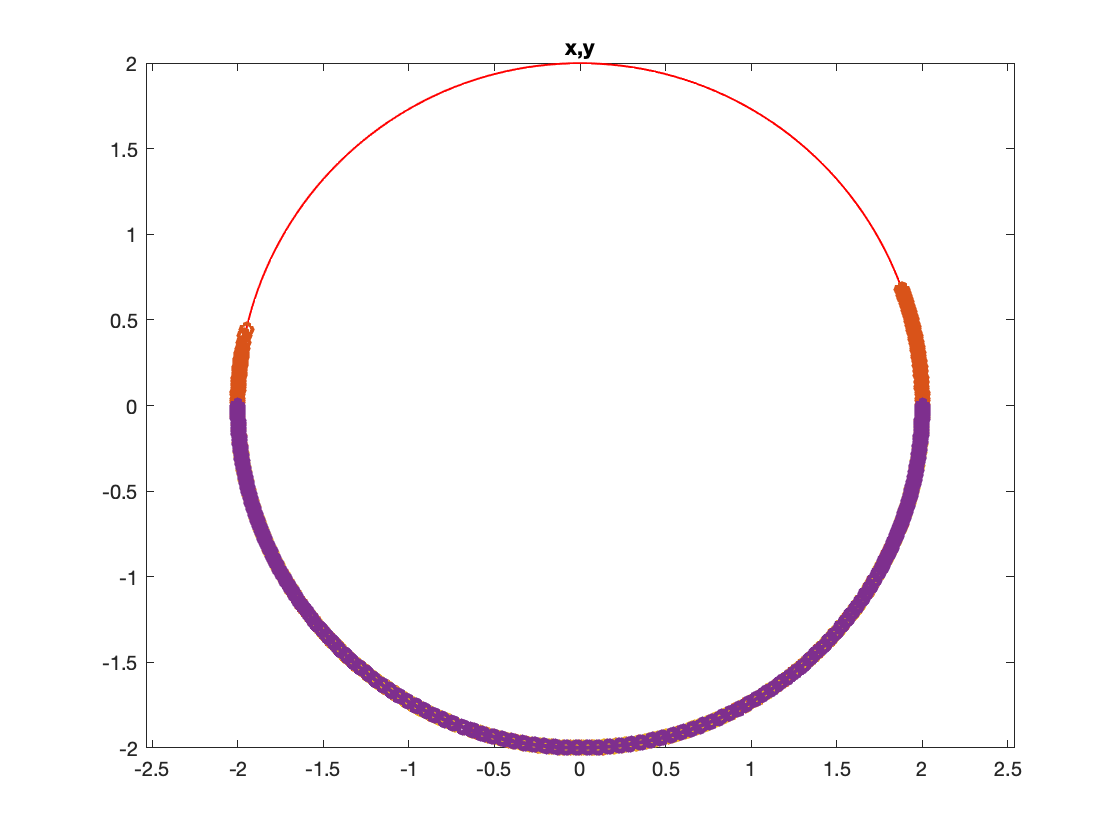

h = figure();
xx = ell*cos(0:pi/100:2*pi);
yy = ell*sin(0:pi/100:2*pi);
plot( xx, yy, '-r', 'Linewidth', 1 );
hold on
axis equal
plot( x_EE, y_EE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_IE, y_IE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_H,  y_H,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

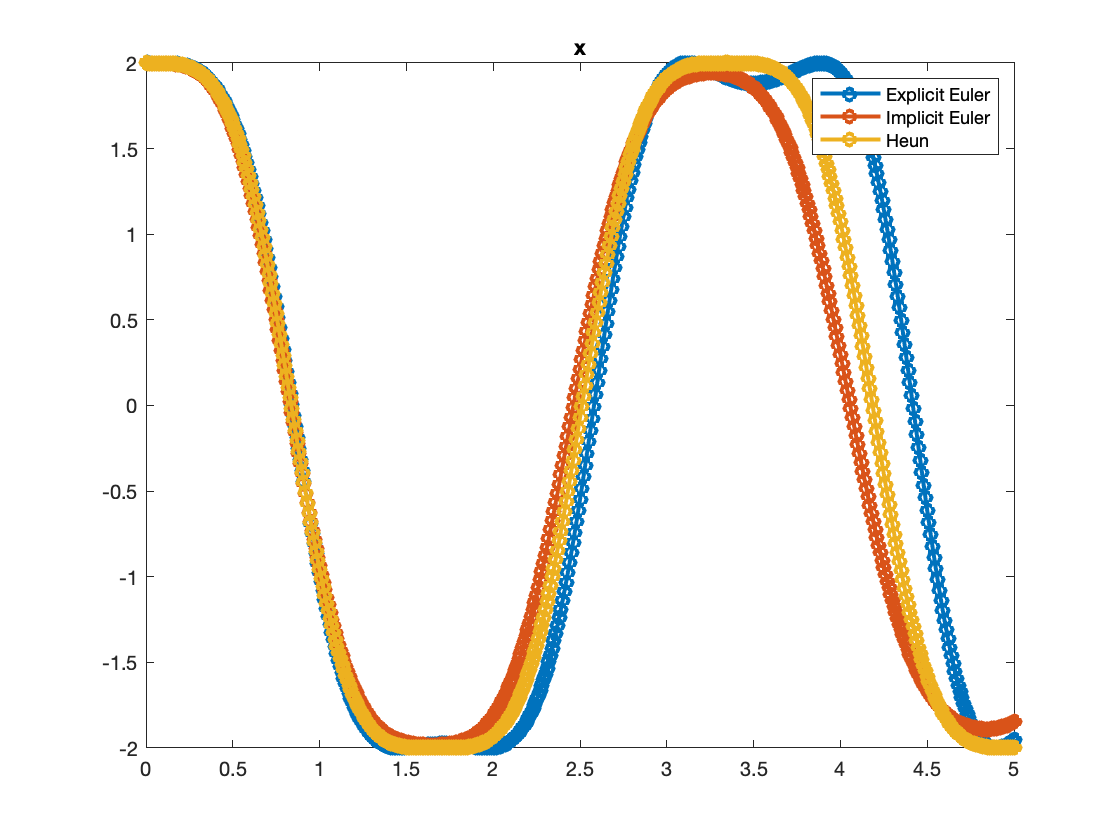

h = figure();
plot( tt, x_EE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_IE, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_H,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend({'Explicit Euler', 'Implicit Euler','Heun'});
title('x');

### Make animation of the solution

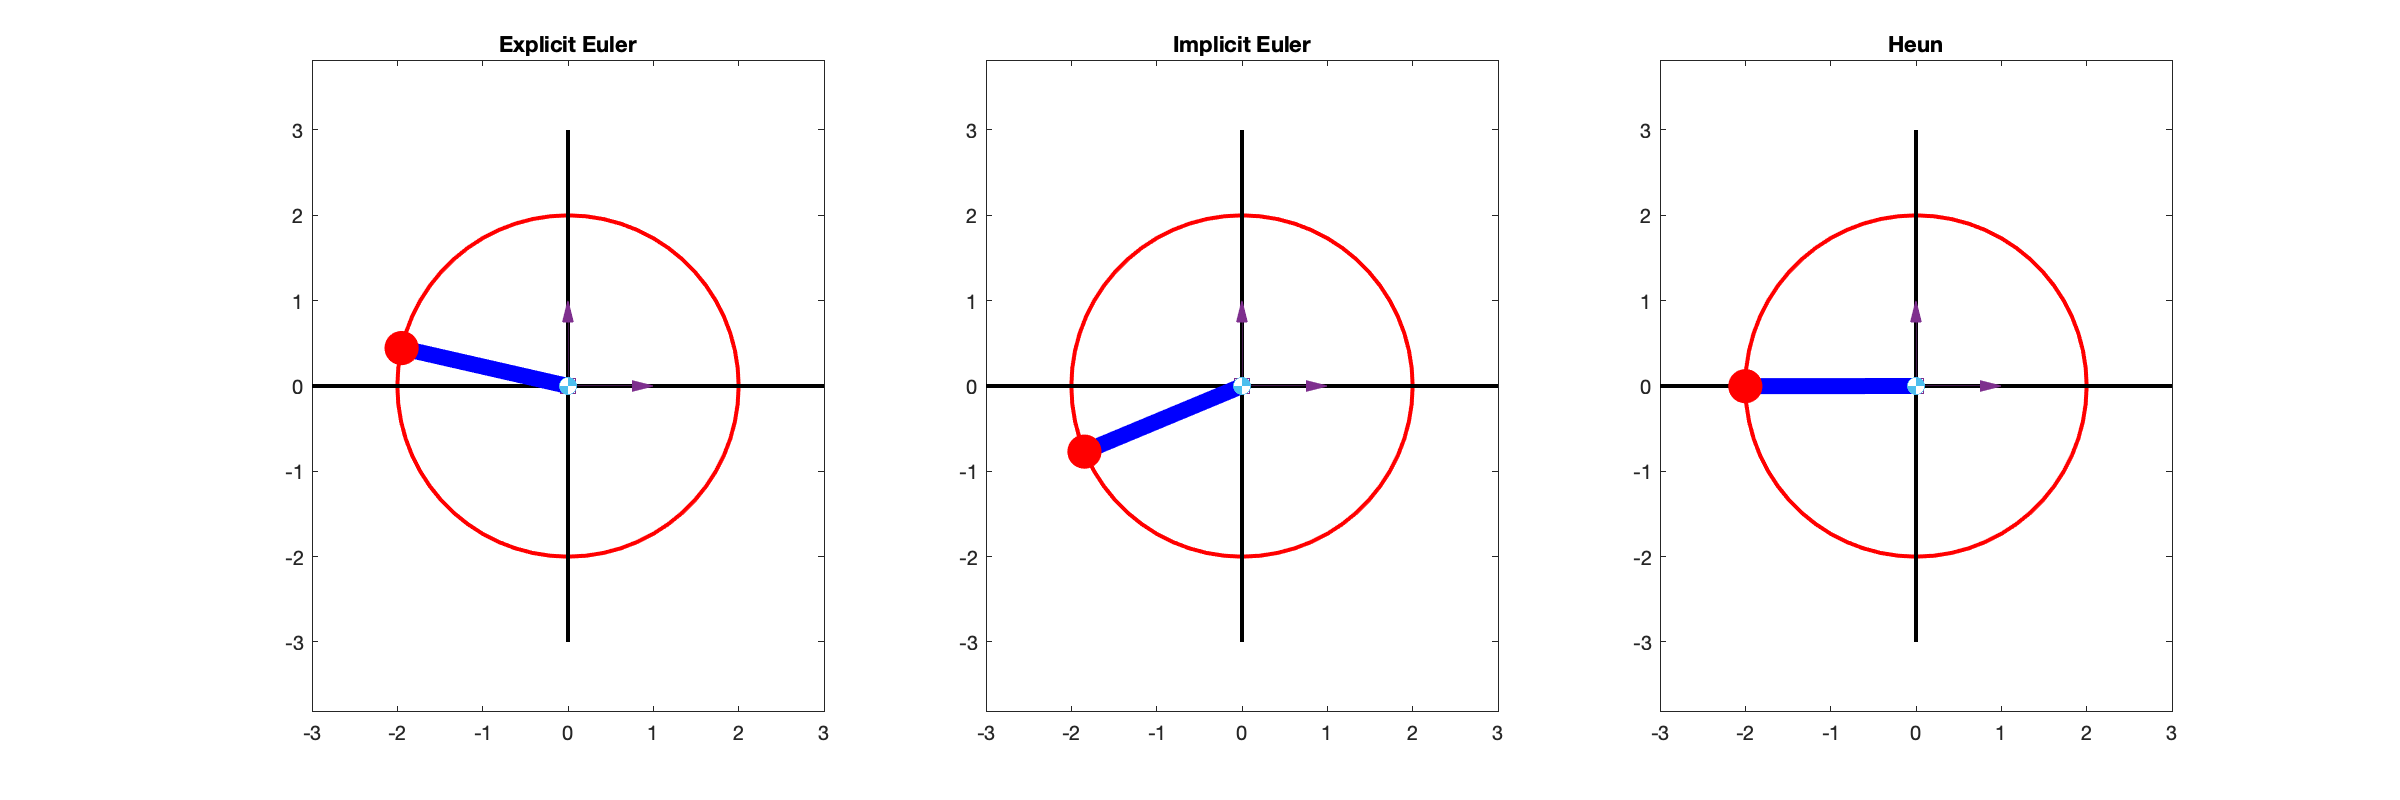

figure('Position', [0 0 1200 400]);
for k=1:10:length(tt)
  subplot(1,3,1);
  ode.plot( tt(k), sol_EE(:,k));
  title('Explicit Euler');
  subplot(1,3,2);
  ode.plot( tt(k), sol_IE(:,k));
  title('Implicit Euler');
  subplot(1,3,3);
  ode.plot( tt(k), sol_H(:,k));
  title('Heun');
  drawnow limitrate;
  pause(0.01);
end